# AuE-6600 | Dynamic Performance of Vehicles

## Midterm Exam

### Problem 1: Power Limit

A proving ground test was performed on a long, straight road to determine the terminal velocity of a certain vehicle. During the test, the on-board instrumentation failed after the following data was acquired:

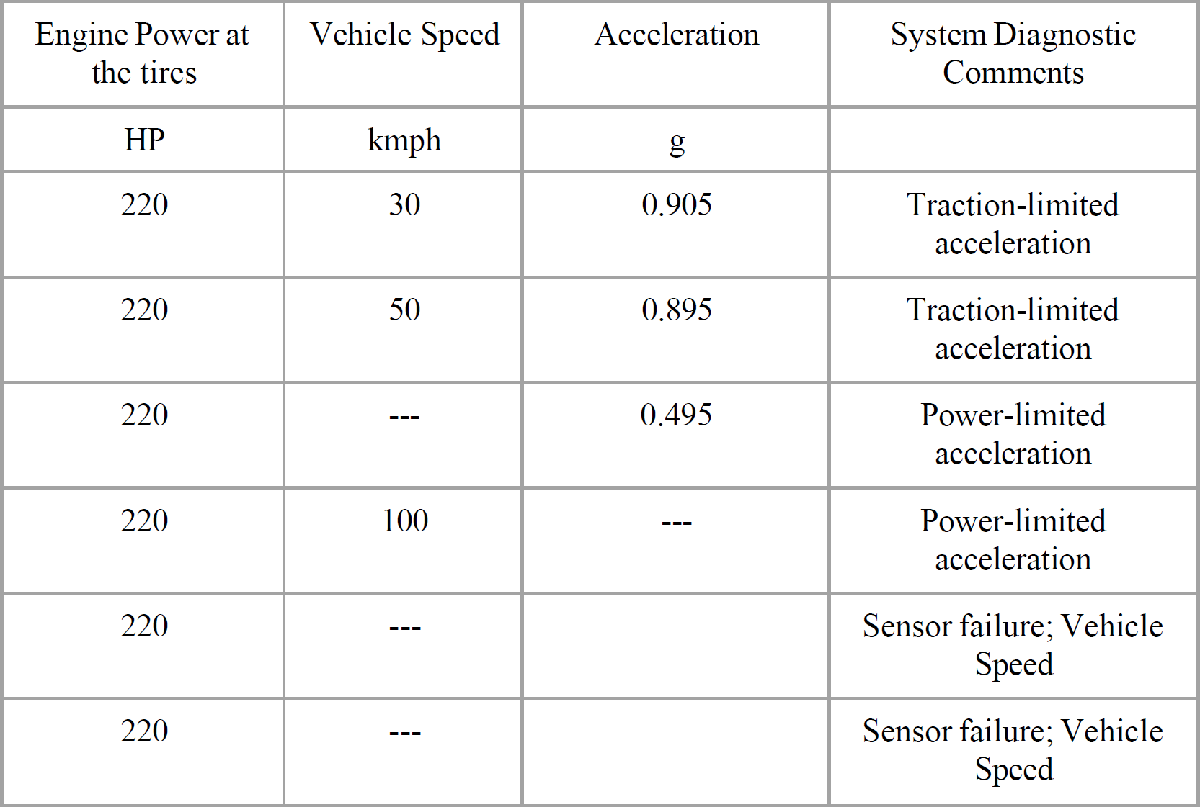

The following information is available:

- Vehicle mass: 1450 kg

- Engine power at the tires: always 220 HP

- Resisting forces: aerodynamic drag and no others

- The car’s aerodynamicist is away on vacation. When reached by cell phone he said the aerodynamic drag force is perfectly modeled by $F=0\ldotp 5\rho \;v^2 C_D A$, but he couldn’t remember values for $C_D$ or $A$.

- Assume standard atmospheric density

- Tires: capable of producing 1.1g of lateral acceleration, longitudinal coefficient of friction, $\mu \;$= 0.91

A. Determine this vehicle’s terminal velocity.

B. Suppose the driver lifts off the throttle at top speed. What instantaneous deceleration will the vehicle experience solely due to aerodynamic drag?

C. Now suppose the vehicle is cornering at 0.5g, with all four tires operating at 5 deg slip angle. Calculate the total induced drag force. (Note: Assume that the friction limit of the tire is not reached!)

D. Write an equation to predict a new terminal velocity at maximum lateral acceleration, accounting for the induced drag. (Do not solve for the new terminal velocity).

### Solution 1

A. Determine this vehicle’s terminal velocity.

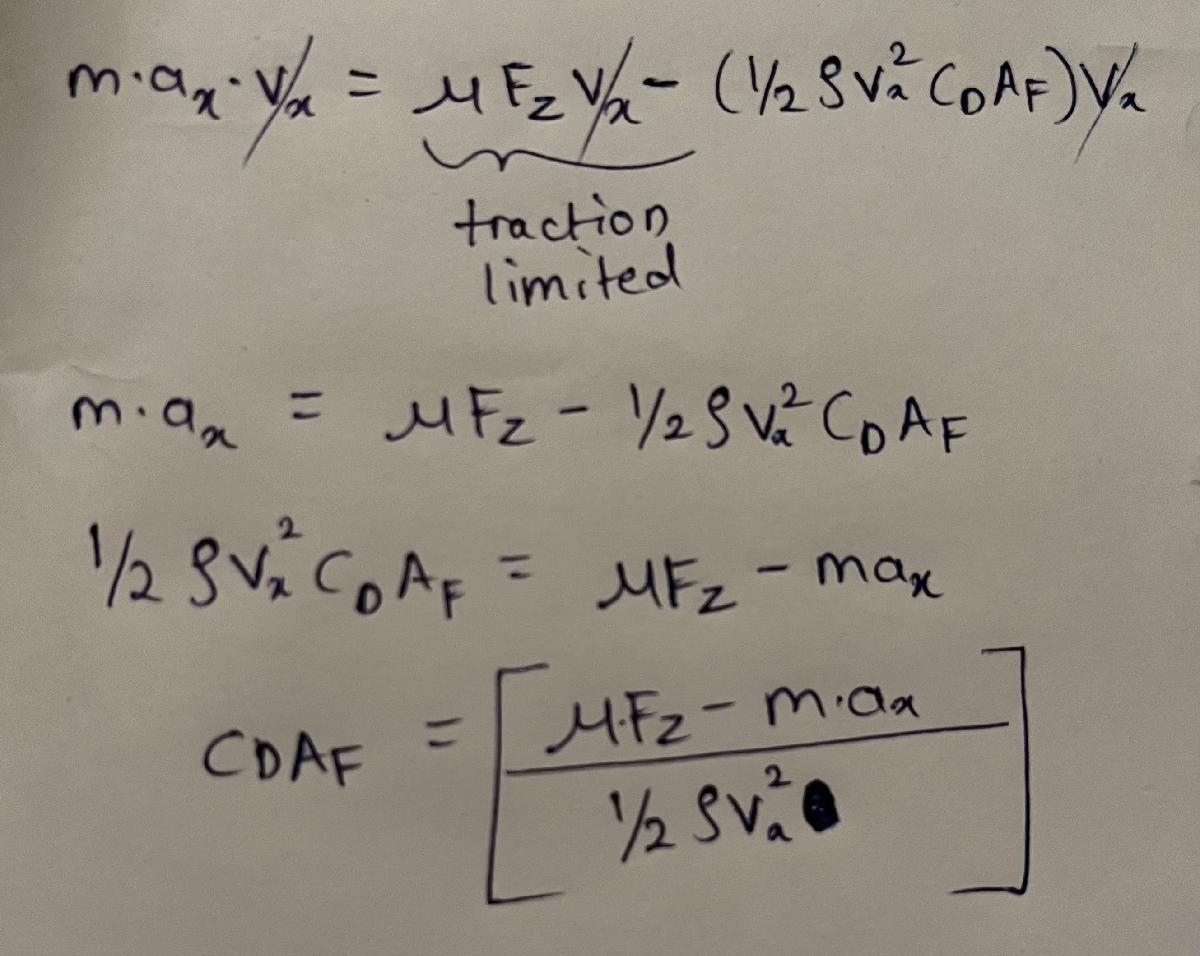 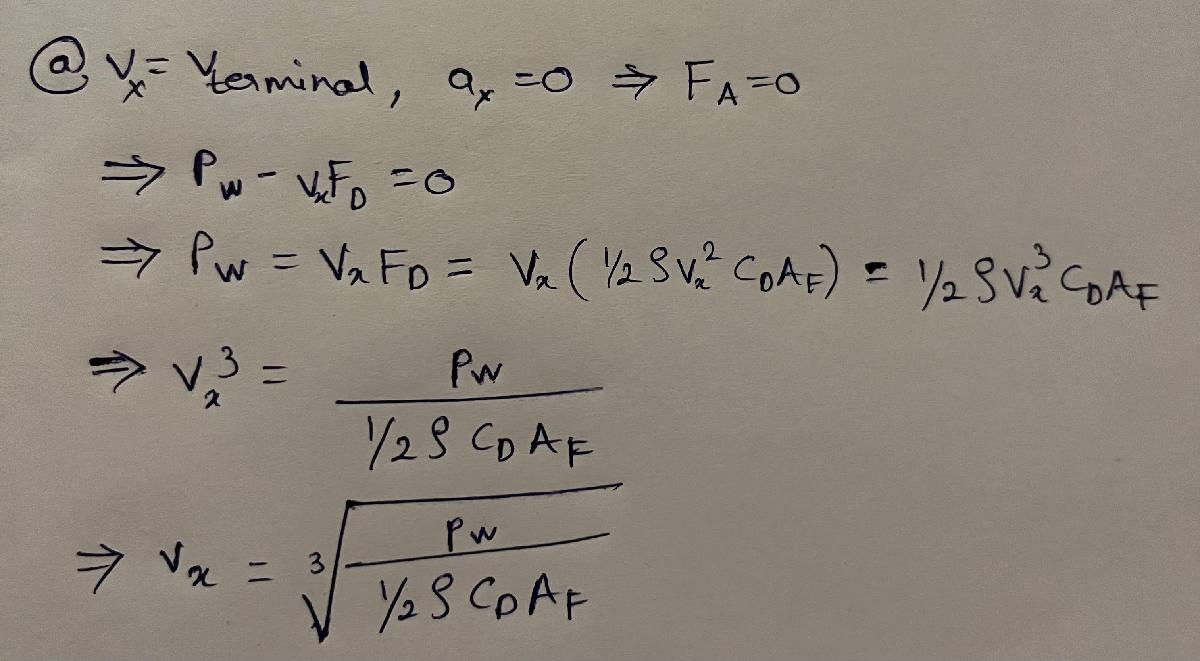

% Given data
m = 1450; % kg
P_w = 220; % hp
P_w = P_w*745.7; % watt
u = 0.91;
Fz = m*9.81; % N
rho = 1.225; % kg/m^3 @ 15 °C, 101.32 kPa
% Calculate C_D*A_F @ 50 kmph
v_x = 50; % km/h
v_x = v_x/3.6; % m/s
a_x = 0.895; % g
a_x = a_x*9.81; % m/s^2
CD_AF_30 = (u*Fz-(m*a_x))/(0.5*rho*v_x^2);
% Calculate C_D*A_F @ 50 kmph
v_x = 30; % km/h
v_x = v_x/3.6; % m/s
a_x = 0.905; % g
a_x = a_x*9.81; % m/s^2
CD_AF_50 = (u*Fz-(m*a_x))/(0.5*rho*v_x^2);
CD_AF = mean([CD_AF_30,CD_AF_50]);
% Calculate terminal velocity
v_terminal = ((P_w)/(0.5*rho*CD_AF))^(1/3); % N
fprintf('The terminal velocity is %.4f m/s', v_terminal);

The terminal velocity is 53.6037 m/s

B. Suppose the driver lifts off the throttle at top speed. What instantaneous deceleration will the vehicle experience solely due to aerodynamic drag?

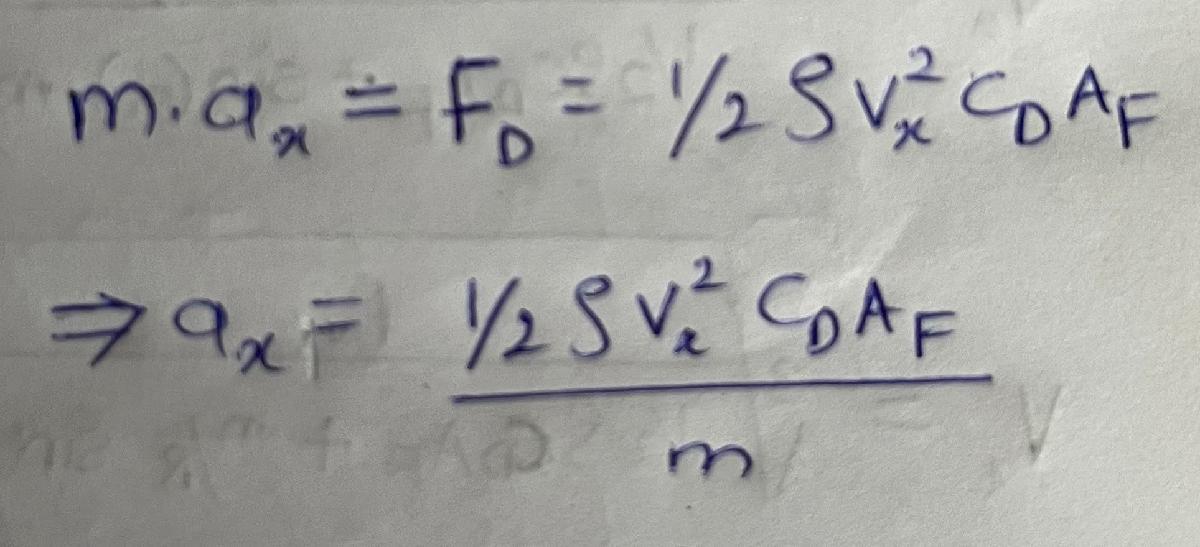

a_x = (0.5*rho*v_terminal^2*CD_AF)/m;
fprintf('The instantaneous deceleration is %.4f m/s^2', a_x);

The instantaneous deceleration is 2.1107 m/s^2

C. Now suppose the vehicle is cornering at 0.5g, with all four tires operating at 5 deg slip angle. Calculate the total induced drag force. (Note: Assume that the friction limit of the tire is not reached!)

% Given data
a_y = 0.5; % g
a_y = a_y *9.81; % m/s^2
alpha = 5; %deg
alpha = deg2rad(alpha); % rad
% Calculate lateral force
F_y = m*a_y; % N
% Calculate total induced drag force
F_ID = F_y*sin(alpha); % N
fprintf('Total induced drag force is %.4f N', F_ID);

Total induced drag force is 619.8734 N

D. Write an equation to predict a new terminal velocity at maximum lateral acceleration, accounting for the induced drag. (Do not solve for the new terminal velocity).

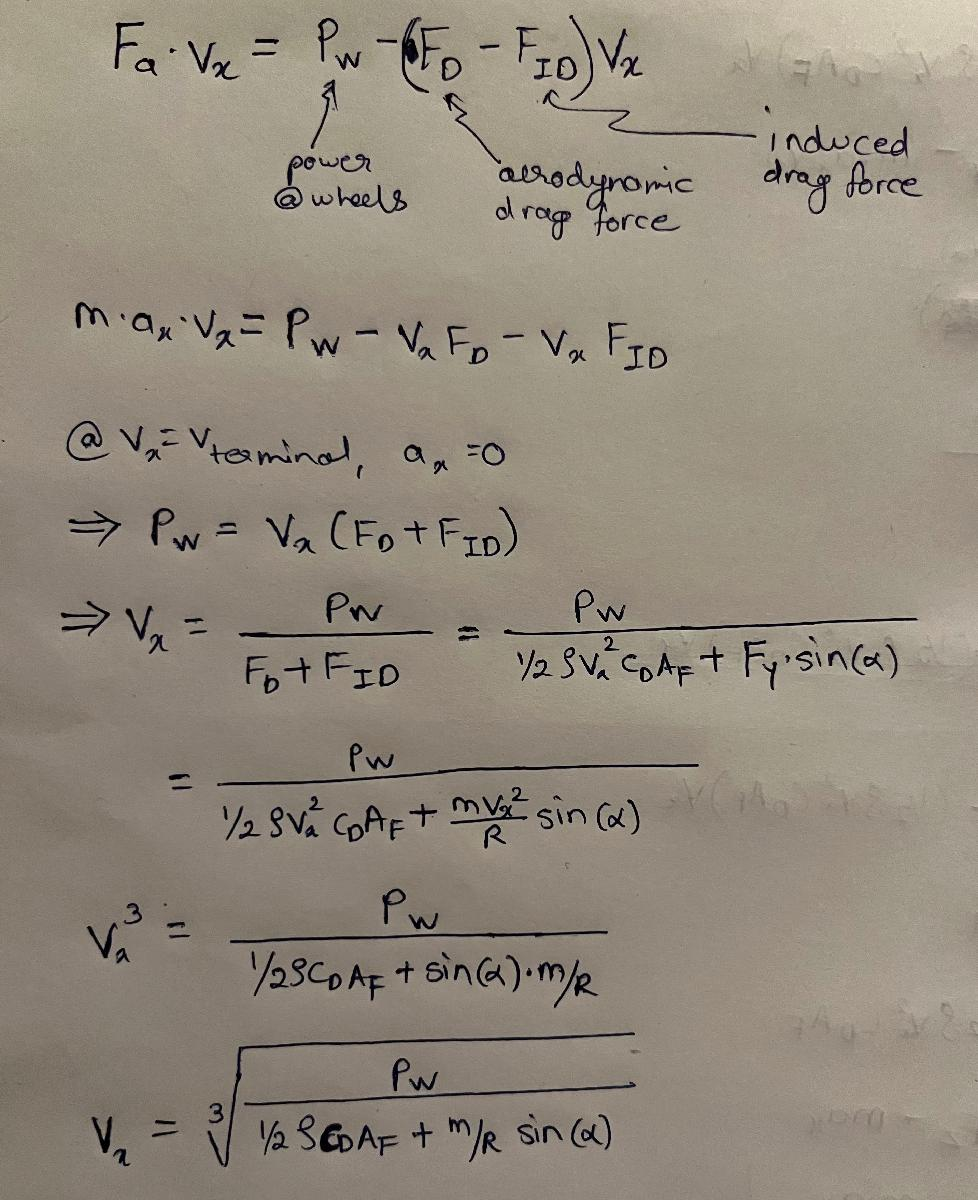

### Problem 2: Tire Dynamics & Bicycle Model

The velocity and lateral acceleration instrumentation on an autonomous car at a proving ground has malfunctioned. In this question you are asked to determine the missing information. Here are the vehicle parameters:

- Mass: 1500 kg

- Drag Coefficient: 0.5

- Frontal Area: 2.2 m^2

- Straight Line Top Speed: 240 km/hour

- Tire Print Length: 0.16 m (Note that this is 2a!)

- Lateral Stiffness per Unit Length of the Tire: 6.25 MN/m^2

- Maximum Friction Coefficient: 1.3

The car was being driven on a very large, constant-radius circle as fast as possible when the instrumentation failed – the vehicle was power limited at the time. The only information available after the instrumentation failed was from the steer-by-wire system which needed to overcome a total self-aligning moment of 160 Nm to steer the car.

A. Using the linear (brush) tire model, determine the total lateral force produced by the tires and determine at what slip angle the tires were running (see assumptions)!

B. What was the speed of the vehicle (see hint!)?

C. What was the lateral acceleration and the radius of the circle?

D. What slip angle would result for the lateral force determined in part A if you employed the brush tire model with parabolic pressure distribution?

E. Given a brush tire model with parabolic pressure distribution, which velocity could the car drive on the circle determined in part C before total sliding would occur?

F. Assume the cornering stiffness from part A for the front tires and a CG location resulting with 55% of the weight at the rear axle. What cornering stiffness would be needed for the rear of the vehicle to make it neutral steer?

Assumptions and Hints:

- For part A, assume that all four tires were running at the same slip angle and produced the same lateral force.

- For part B, determine the maximum engine power from the straight-line condition, then account for the induced drag effect (rearward component of the lateral force with respect to the velocity vector) while cornering to determine the speed.

- For part D and E, assume that there is no load transfer, and that the vehicle is perfectly balanced, i.e., the vehicle mass is distributed evenly to all four tires.

### Solution 2

% Given data
m = 1500; % kg
C_D = 0.5;
A_F = 2.2; % m^2
v_max = 240; % km/h
v_max = v_max/3.6; % m/s
a = 0.5*0.16; % m
c = 6.25; % MN/m^2
c = c*1e6; % N/m^2
u = 1.3;
Mz = 160; % Nm

A. Using the linear (brush) tire model, determine the total lateral force produced by the tires and determine at what slip angle the tires were running (assume that all four tires were running at the same slip angle and produced the same lateral force).

Fy = Mz*3/a;
alpha = Fy/(2*c*a^2);
fprintf('The lateral force produced by the tires is %d N and the slip angle at which the tires were running is %.4f deg', Fy, rad2deg(alpha));

The lateral force produced by the tires is 6000 N and the slip angle at which the tires were running is 4.2972 deg

B. What was the speed of the vehicle (determine the maximum engine power from the straight-line condition, then account for the induced drag effect while cornering to determine the speed)?

rho = 1.225; % kg/m^3 @ 15 °C, 101.32 kPa
P_w = (0.5*rho*v_max^2*C_D*A_F)*v_max; % watt
F_ID = Fy*sin(alpha); % N
F_D = 0.5*rho*v_max^2*C_D*A_F; % N
v_x = P_w/(F_D+F_ID);
fprintf('The speed of the vehicle was %.4f m/s', v_x);

The speed of the vehicle was 57.9641 m/s

C. What was the lateral acceleration and the radius of the circle?

a_y = Fy/m;
R = v_x^2/a_y;
fprintf('The lateral acceleration is %d m/s^2 and the radius of the circle is %.4f m', a_y, R);

The lateral acceleration is 4 m/s^2 and the radius of the circle is 839.9588 m

D. What slip angle would result for the lateral force determined in part A if you employed the brush tire model with parabolic pressure distribution?

Fz = m*9.81; % N
theta = (2*c*a^2)/(3*u*Fz/4);
% Fy = u*Fz*((3*theta*Sy)-(3*theta^2*Sy^2)+(theta^3*Sy^3))
Sy = roots([theta^3 -3*theta^2 3*theta -(Fy/4)/(u*Fz/4)]);
Sy = Sy(imag(Sy)==0);
alpha_p = atan(Sy);
fprintf('The slip angle (for brush tire model with parabolic pressure distribution) is %.4f deg', rad2deg(alpha_p));

The slip angle (for brush tire model with parabolic pressure distribution) is 1.2113 deg

E. Given a brush tire model with parabolic pressure distribution, which velocity could the car drive on the circle determined in part C before total sliding would occur?

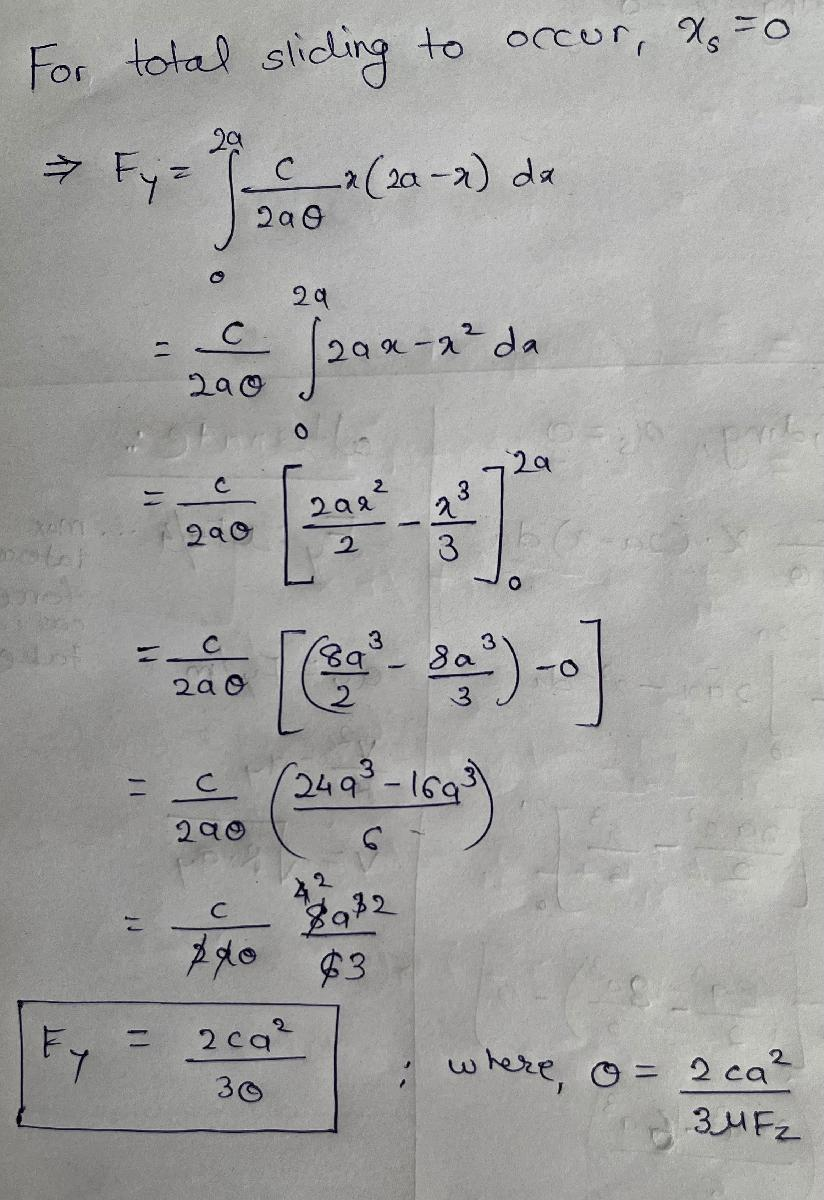

theta = (2*c*a^2)/(3*u*Fz/4);
Fy_p = (2*c*a^2)/(3*theta);
a_y = Fy_p/m;
v_x = sqrt(R*a_y);
fprintf('The velocity at which the car can drive on the circle before total sliding would occur is %.4f m/s', v_x);

The velocity at which the car can drive on the circle before total sliding would occur is 51.7494 m/s

F. Assume the cornering stiffness from part A for the front tires and a CG location resulting with 55% of the weight at the rear axle. What cornering stiffness would be needed for the rear of the vehicle to make it neutral steer?

c_alpha_F = (Fy/4)/alpha;
a_by_b = 0.55/0.45;
c_alpha_R = a_by_b*c_alpha_F;
fprintf('The cornering stiffness needed for the rear of the vehicle to make it neutral steer is %.4f kN/rad', c_alpha_R/1000);

The cornering stiffness needed for the rear of the vehicle to make it neutral steer is 24.4444 kN/rad

### Problem 3: Tire Dynamics & Semi-Emperical Model

Please note that the questions below are all separate parts with separate values given.

#### A. Non-dimensional Tire Model

The three equations below represent a Nondimensional Tire Model for a certain tire. Expand the model to determine the lateral force at 4 deg slip angle, –1200 lb normal load.


$$\mu =2+0\ldotp 0004\;F_Z$$



$$c=0\ldotp 0003F_Z^2 +0\ldotp 8F_Z$$



$$\bar{F} =\sin \left(1\ldotp 4\tan^{-1} \left(0\ldotp 7\bar{\alpha \;} \right)\right)$$


Note: B = 0.7, C = 1.4, D = 1, E = 0.

#### B. Brush Model:

The load of the tire is 4500 N, the contact patch length of the tires is 8 cm, the slip ratio is 0.15, the coefficient of friction is 0.8, and the longitudinal stiffness of the tire is $c_x$ = 1300 N/cm^2. Based on the brush model, calculate the longitudinal force under this slip ratio.

#### C. Pacejka Model:

The load of the tire is $F_Z$ = 4500 N. The coefficient of road adhesion is $\mu_p$ = 1.0 and $\mu_s$ = 0.7. When the slip ratio is s = 0.04, the longitudinal force is $F_X$ = 1000 N. When s = 0.2, then $F_X$ reaches the maximum value. Based on the H.B. Pacejka magic formula model, analyze the relationships between the longitudinal force and the slip ratio.

### Solution 3

A. Non-dimensional Tire Model

% Given data
SA = 4; % deg
SA = deg2rad(SA); % rad
Fz = -1200; % lb
Fz = Fz*4.4482; % N

u = 2+(0.0004*Fz);
c = (0.0003*Fz^2)+(0.8*Fz);
alpha_bar = (c*tan(SA))/(u*Fz);
Fy_bar = sin(1.4*atan(0.7*alpha_bar));
Fy = Fy_bar*u*Fz;
fprintf('The lateral force is %.4f N', Fy);

The lateral force is 277.9096 N

B. Brush Model:

% Given data
Fz = 4500; % N
a = 0.5*8; % cm
a = a/100; % m
K = 0.15;
u = 0.8;
c_x = 1300; % N/cm^2
c_x = c_x*1e4; % N/m^2

% Using analytical model I (linear)
Fx = 2*c_x*a^2*K;
fprintf('The longitudinal force (using analytical model I) is %.4f N', Fx);

The longitudinal force (using analytical model I) is 6240.0000 N

% Using analytical model II (bi-linear)
Sx = K/(1+K);
Fx = (u*Fz)-((u^2*Fz^2)/(8*c_x*a^2*Sx));
fprintf('The longitudinal force (using analytical model II) is %.4f N', Fx);

The longitudinal force (using analytical model II) is 3002.8846 N

% Using analytical model III (parabolic)
theta = (2*c_x*a^2)/(3*u*Fz);
Sx = K/(1+K);
Fx = u*Fz*((3*theta*Sx)-(3*theta^2*Sx^2)+(theta^3*Sx^3));
fprintf('The longitudinal force (using analytical model III) is %.4f N', Fx);

The longitudinal force (using analytical model III) is 3156.4903 N

C. Pacejka Model:

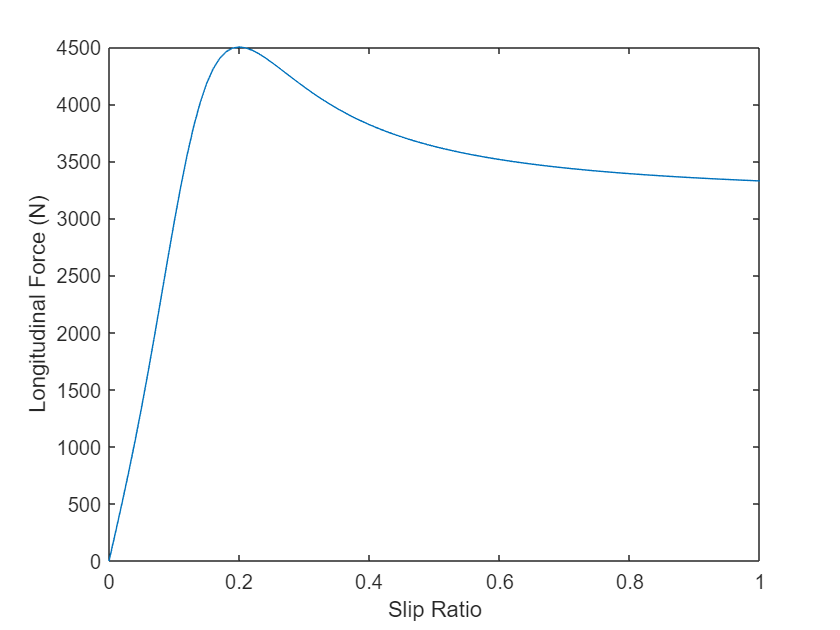

% Given data
Fz = 4500; % N
up = 1;
us = 0.7;
K1 = 0.04;
Fx1 = 1000; % N
K2 = 0.2;
Fx2 = up*Fz; % N
% Derive dimensional Pacekja coefficients from data
D = Fx2; % N
x_m = K2;
y_s = us*Fz; % N
BCD = Fx1/K1; % N (assuming 0 inclination angle)
C = 1+(1-((2/pi)*asin(y_s/D)));
B = BCD/(C*D);
E = ((B*x_m)-tan(pi/(2*C)))/((B*x_m)-atan(B*x_m));
% Analyze relationship b/w Fx and K based on Pacejka MF model 
K = 0:0.01:1;
Fx = D*sin(C*atan((B*K)-E*((B*K)-atan((B*K)))));
figure()
plot(K,Fx)
xlabel("Slip Ratio")
ylabel("Longitudinal Force (N)")

### Problem 4: Tire Data Processing

The table contains tire data recorded at a nonzero inclination angle. Determine the following at –5.55kN normal load.

A. Cornering stiffness

B. Left turn lateral friction coefficient (at positive slip angles)

C. Vertical spring rate (at zero slip angle)

D. Induced drag at +3 deg slip angle

Columns are normal load (FZ), slip angle (SA), inclination angle (IA), inflation pressure (P), lateral force (FY) and loaded radius (RL)

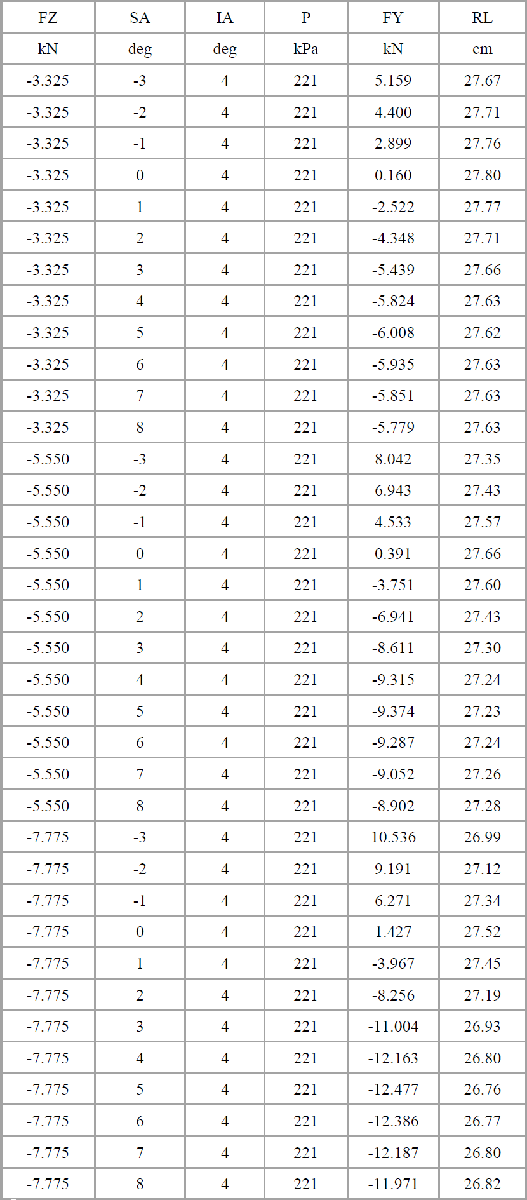

### Solution 4

% Load data
FZ = [-3.325 -3.325 -3.325 -3.325 -3.325 -3.325 -3.325 -3.325 -3.325 -3.325 -3.325 -3.325 -5.55 -5.55 -5.55 -5.55 -5.55 -5.55 -5.55 -5.55 -5.55 -5.55 -5.55 -5.55 -7.775 -7.775 -7.775 -7.775 -7.775 -7.775 -7.775 -7.775 -7.775 -7.775 -7.775 -7.775]; % kN
SA = [-3 -2 -1 0 1 2 3 4 5 6 7 8 -3 -2 -1 0 1 2 3 4 5 6 7 8 -3 -2 -1 0 1 2 3 4 5 6 7 8]; % deg
IA = [4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4]; % deg
P = [221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221]; % kPa
FY = [5.159 4.4 2.899 0.16 -2.522 -4.348 -5.439 -5.824 -6.008 -5.935 -5.851 -5.779 8.042 6.943 4.533 0.391 -3.751 -6.941 -8.611 -9.315 -9.374 -9.287 -9.052 -8.902 10.536 9.191 6.271 1.427 -3.967 -8.256 -11.004 -12.163 -12.477 -12.386 -12.187 -11.971]; % kN
RL = [27.67 27.71 27.76 27.8 27.77 27.71 27.66 27.63 27.62 27.63 27.63 27.63 27.35 27.43 27.57 27.66 27.6 27.43 27.3 27.24 27.23 27.24 27.26 27.28 26.99 27.12 27.34 27.52 27.45 27.19 26.93 26.8 26.76 26.77 26.8 26.82]; % cm
% Convert units to SI
FZ = FZ*1000; % N
SA = deg2rad(SA); % rad
IA = deg2rad(IA); % rad
P = P*1000; % Pa
FY = FY*1000; % N
RL = RL/100; % m
% Filter data for FZ = -5.55 kN normal load
[FZ_desired,SA_desired,IA_desired,P_desired,FY_desired,RL_desired] = deal([]);
for i = 1:length(FZ)
    if FZ(i) == -5550
        FZ_desired(end+1) = FZ(i);
        SA_desired(end+1) = SA(i);
        IA_desired(end+1) = IA(i);
        P_desired(end+1) = P(i);
        FY_desired(end+1) = FY(i);
        RL_desired(end+1) = RL(i);
    end
end

A. Cornering stiffness

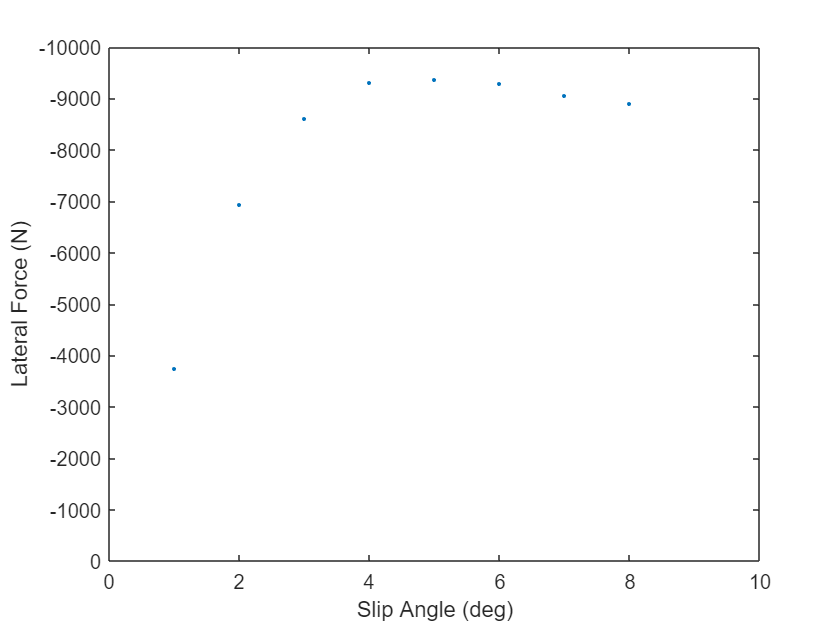

% Plot FY vs SA data for each FZ
figure()
plot(rad2deg(SA_desired),FY_desired, '.')
xlabel("Slip Angle (deg)")
ylabel("Lateral Force (N)")
set(gca,'YDir','reverse') % Invert Y-axis to match RCVD convention
xlim([0, 10]) % Limit X-axis to 1st quadrant to match RCVD convention
ylim([-1e4, 0]) % Limit (inverted) Y-axis to 1st quadrant to match RCVD convention

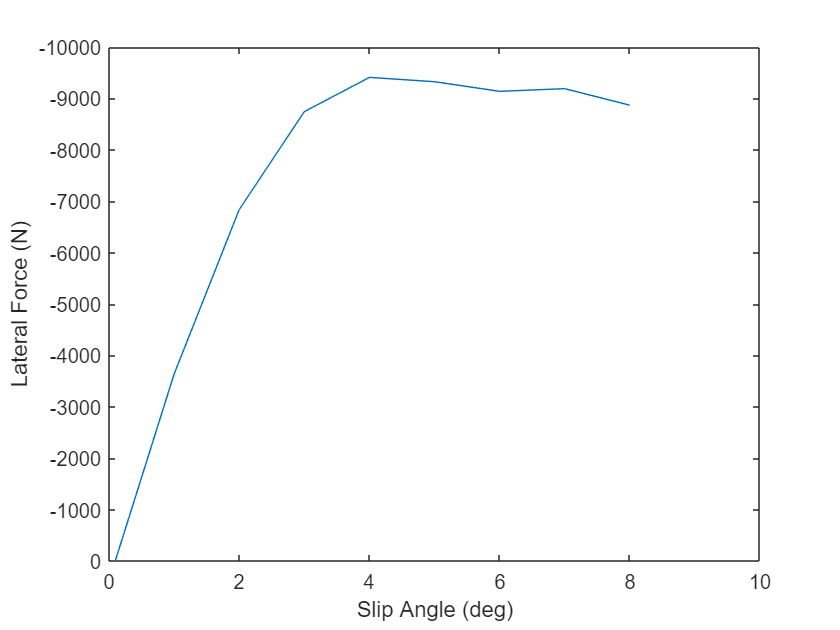

% Fit polinomial to FY vs SA data
poly_FY_SA = polyfit(SA_desired,FY_desired,6);
% Plot polinomials fit to FY vs SA data
figure()
plot(rad2deg(SA_desired),polyval(poly_FY_SA,SA_desired))
xlabel("Slip Angle (deg)")
ylabel("Lateral Force (N)")
set(gca,'YDir','reverse') % Invert Y-axis to match RCVD convention
xlim([0, 10]) % Limit X-axis to 1st quadrant to match RCVD convention
ylim([-1e4, 0]) % Limit (inverted) Y-axis to 1st quadrant to match RCVD convention

% Take derivative of polinomial fit to FY vs SA data
poly_prime = polyder(poly_FY_SA);
% Evaluate derivative at SA = 0 deg (this is the cornering stiffness)
c = polyval(poly_prime, 0);
fprintf('The cornering stiffness is %.4f kN/rad', c/1000);

The cornering stiffness is -238.0767 kN/rad

B. Left turn lateral friction coefficient (at positive slip angles)

u = min(FY_desired)/(-5550);
fprintf('Left turn lateral friction coefficient (at positive slip angles) is %.4f', u);

Left turn lateral friction coefficient (at positive slip angles) is 1.6890

C. Vertical spring rate (at zero slip angle)

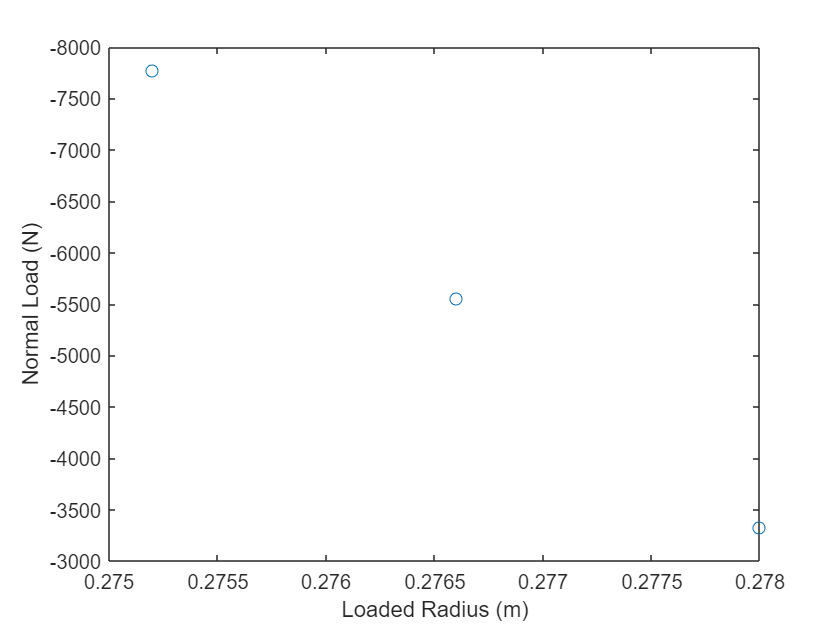

% Filter data for SA = 0 deg
[FZ_desired,RL_desired] = deal([]);
for i = 1:length(SA)
    if SA(i) == 0
        FZ_desired(end+1) = FZ(i);
        RL_desired(end+1) = RL(i);
    end
end
% Plot FZ vs RL data
figure()
plot(RL_desired,FZ_desired,'o')
xlabel("Loaded Radius (m)")
ylabel("Normal Load (N)")
set(gca,'YDir','reverse') % Invert Y-axis to match RCVD convention

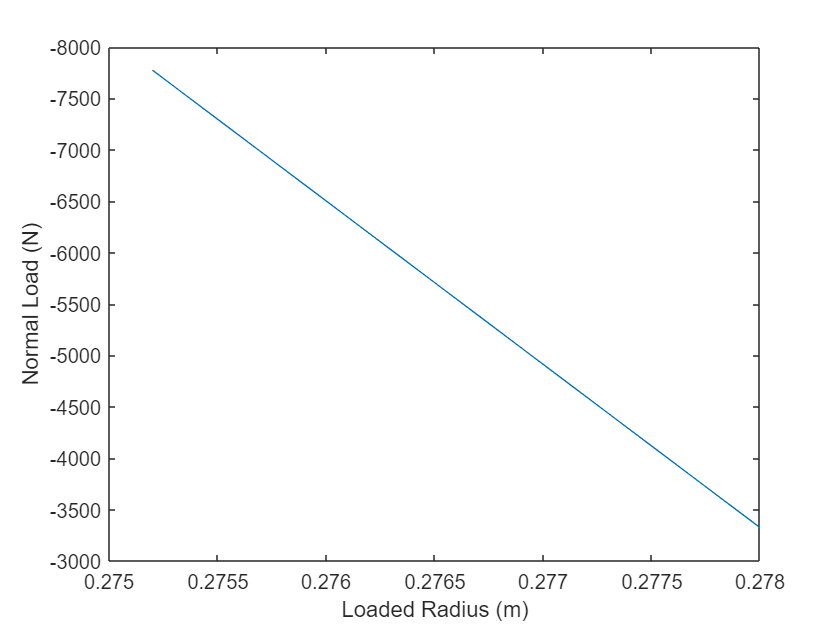

% Fit polinomial to FZ vs RL data (fit a straight line since w.k.t. spring exhibits linear dynamics)
poly_FZ_RL = polyfit(RL_desired,FZ_desired,1);
% Plot polinomial fit to FZ vs RL data
figure()
plot(RL_desired,polyval(poly_FZ_RL,RL_desired))
xlabel("Loaded Radius (m)")
ylabel("Normal Load (N)")
set(gca, 'YDir','reverse') % Invert Y-axis to match RCVD convention

% Slope of line fit to FZ vs RL data is the vertical spring rate
spring_rate = polyder(poly_FZ_RL);
fprintf("Vertical spring rate (at zero slip angle) is %.4f kN/m", spring_rate/1000)

Vertical spring rate (at zero slip angle) is 1589.2857 kN/m

D. Induced drag at +3 deg slip angle

% Filter data for SA = 3 deg and FZ = -5550 N
[FY_desired] = deal([]);
for i = 1:length(SA)
    if SA(i) == deg2rad(3) && FZ(i) == -5550
        FY_desired(end+1) = FY(i);
    end
end
F_ID = FY_desired*sin(deg2rad(3)); % N
fprintf("Induced drag at +3 deg slip angle is %.4f N", F_ID)

Induced drag at +3 deg slip angle is -450.6649 N

### Problem 5: Transport Theorem

Consider a small disk with radius $\rho$ that rolls without slipping inside a large hoop of radius R as shown. Frame N is fixed to the hoop, frame $\epsilon$ is fixed to the lever arm that connects the disk to the center of hoop, and the frame B isfixed to the disk. Point O is the center of the hoop, point O’ is the center of the disk, and point p is fixed in the disk. The distance from O’ to p is ρ. Assuming rolling without slipping and the lever is rotating at a constant rate $\omega =\dot{\theta}$, Determine the inertial acceleration of point p expressed in $\epsilon$ coordinates. Give answer in terms of $\omega$, L, R, $\rho$ and $\phi$. (Hint: Refer to Lecture notes)

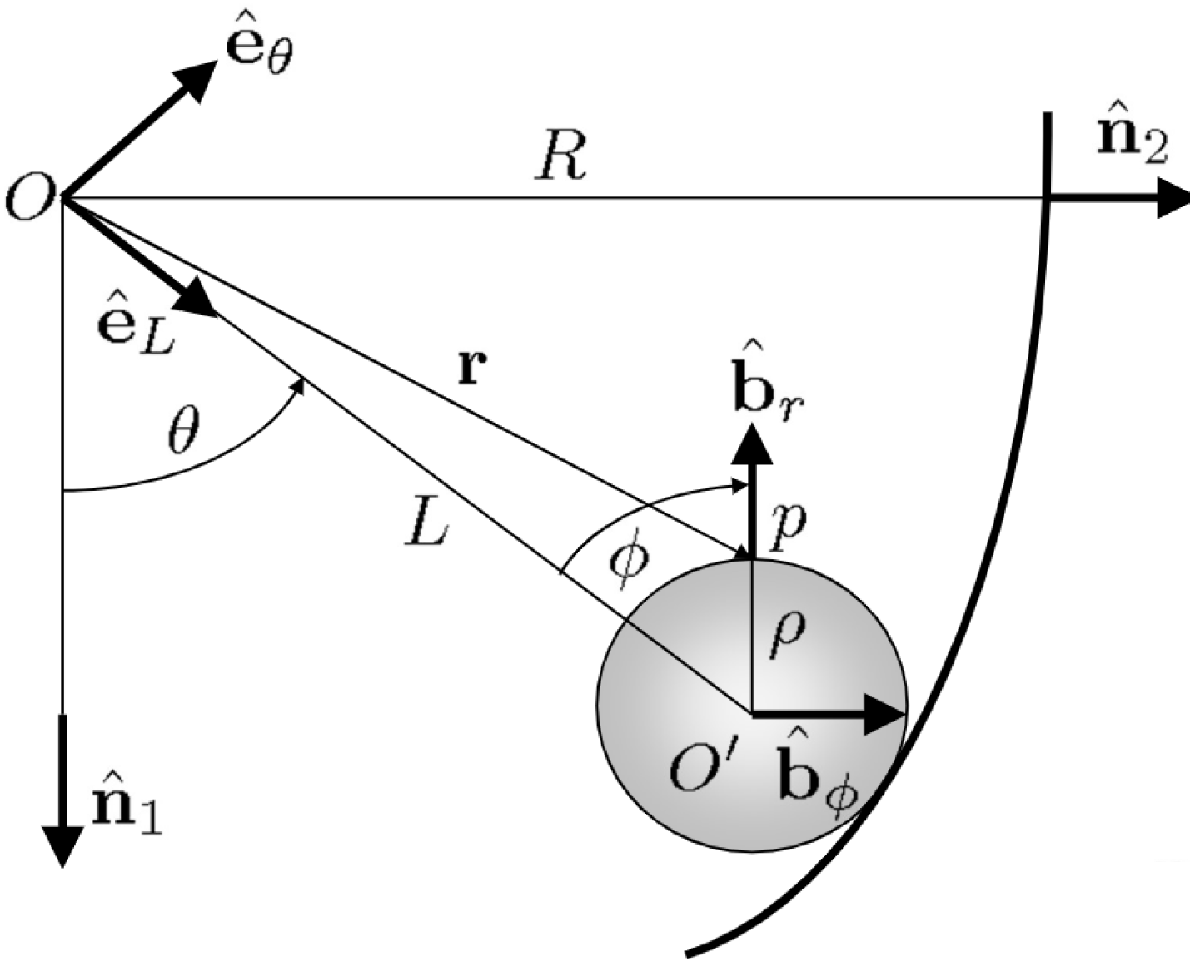

### Solution 5

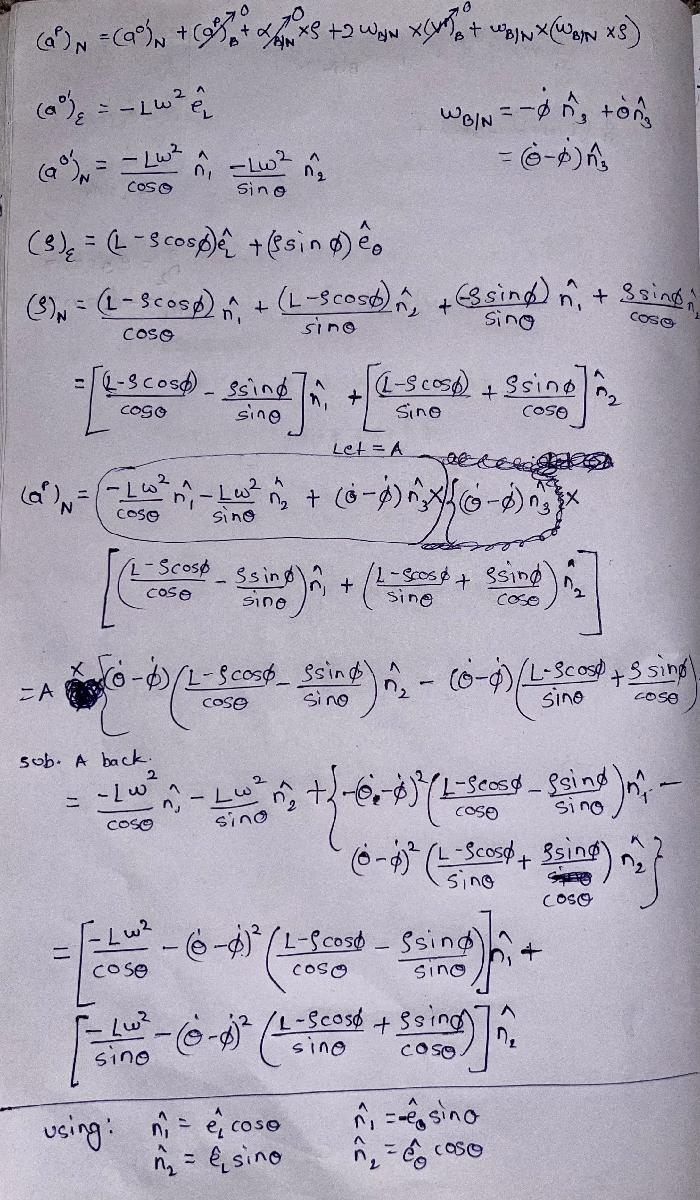

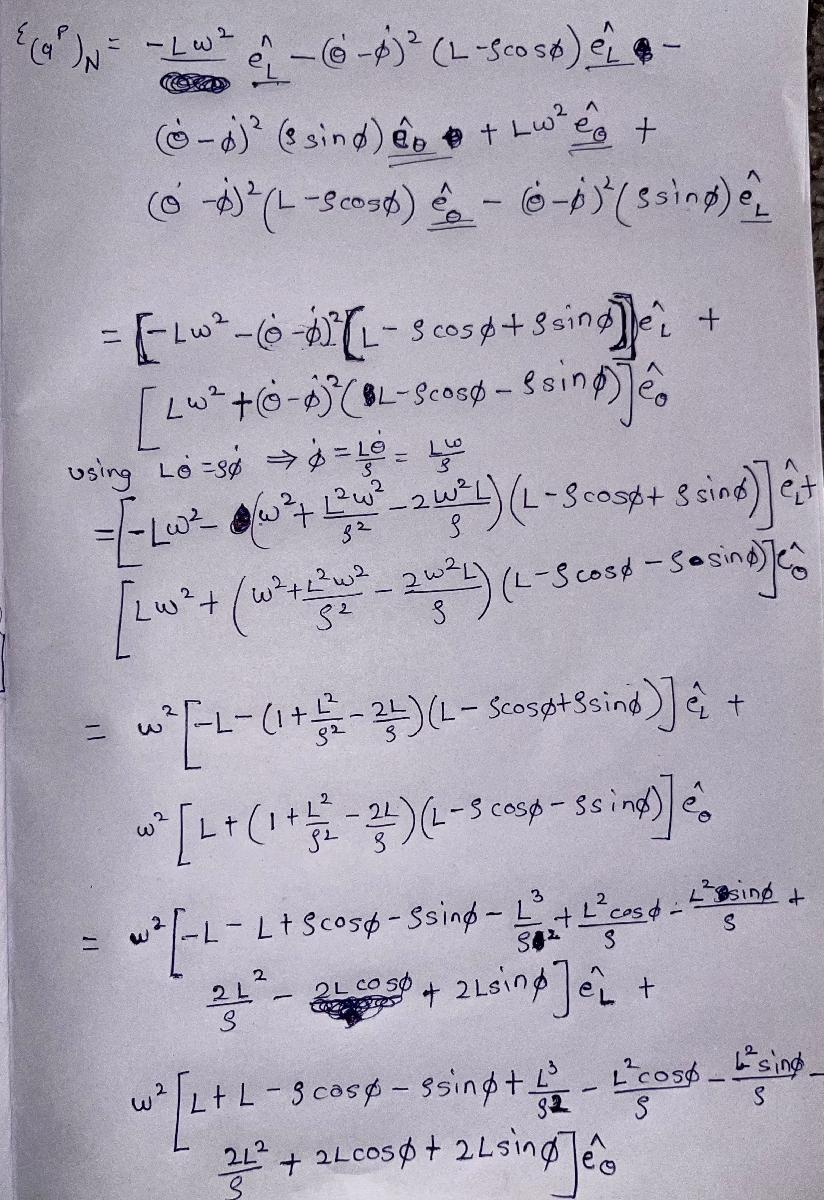

### Problem 6: Racetrack

Assume a racecar has acceleration limits as shown in the g-g diagram below. For simplicity, the maximum driving acceleration is assumed to be constant - a power-limited value estimated for the expected velocity range. Cornering and braking limits are also assumed to be velocity independent.

Determine the minimum time solution for this car to complete a lap of the track below. Solve for a “flying lap” - the car does not start from zero velocity. Each of the two straightaways are 0.45 miles long, and both corners are 180 deg and with radii R2=180 m and R1=230 m. Assume counterclockwise direction (left turns). Loop is along WXYZ

To simplify the calculations, assume the car accelerates in only one direction at a time - thus holding constant speed while cornering. Assume the transitions between the straightaways and the corners (a change in radius) happen instantaneously. Assume that the corners have a constant radius.

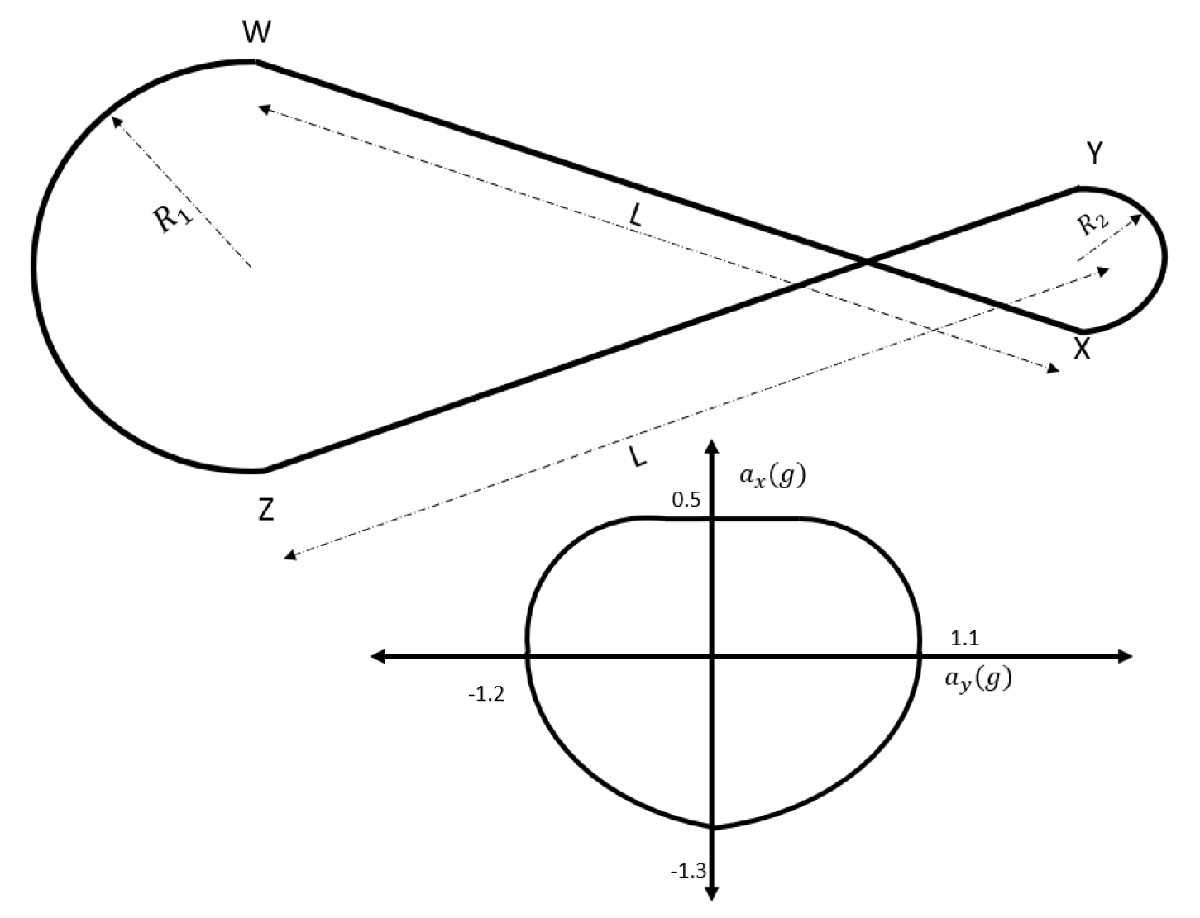

In the end, report the following (note that these quantities are not necessarily computed in this order):

A. Minimum time required for one lap

B. Average speed for one lap

C. The cornering speeds

D. The maximum speed achieved on the straights

E. The location of the braking transition point (measured as a distance from the previous corner)

### Solution 6

C. The cornering speeds

R1 = 230; % m
R2 = 180; % m
a_y_l = -1.2; % g
a_y_l = a_y_l*9.81; % m/s^2
a_y_r = 1.1; % g
a_y_r = a_y_r*9.81; % m/s^2

v_cor_1 = abs(sqrt(R1*a_y_r)); % m/s
v_cor_2 = abs(sqrt(R2*a_y_l)); % m/s
fprintf('The cornering speed for turn ZW (R = 230 m) is %.4f m/s, and that for turn XY (R = 180 m) is %.4f m/s', v_cor_1, v_cor_2);

The cornering speed for turn ZW (R = 230 m) is 49.8190 m/s, and that for turn XY (R = 180 m) is 46.0322 m/s

E. The location of the braking transition point (measured as a distance from the previous corner)

v_i_a_1 = v_cor_1; % m/s
v_i_a_2 = v_cor_2; % m/s
v_i_b_1 = v_cor_2; % m/s
v_i_b_2 = v_cor_1; % m/s
a_x_a = 0.5; % g
a_x_a = a_x_a*9.81; % m/s^2
a_x_b = -1.3; % g
a_x_b = a_x_b*9.81; % m/s^2
L = 0.45; % miles
L = L*1609.34; % m

S_T_1 = (v_i_b_1^2 - v_i_a_1^2 + (2*abs(a_x_b)*L)) / (2 * (a_x_a + abs(a_x_b)));
S_T_2 = (v_i_b_2^2 - v_i_a_2^2 + (2*abs(a_x_b)*L)) / (2 * (a_x_a + abs(a_x_b)));
fprintf('The location of braking transition point for straight WX is %.4f m, and that for straight YZ is %.4f m', S_T_1, S_T_2);

The location of braking transition point for straight WX is 512.7577 m, and that for straight YZ is 533.3133 m

D. The maximum speed achieved on the straights

v_max_1 = abs(sqrt(v_i_a_1^2 + (2 * a_x_a * S_T_1)));
v_max_2 = abs(sqrt(v_i_a_2^2 + (2 * a_x_a * S_T_2)));
fprintf('The maximum speed achieved on straight WX is %.4f m/s, and that on straight YZ is %.4f m/s', v_max_1, v_max_2);

The maximum speed achieved on straight WX is 86.6723 m/s, and that on straight YZ is 85.7366 m/s

B. Average speed for one lap

% Length of Straights
L = 0.45; % miles
L = L*1609.34; % m
% Length of Curves
C1 = pi*R1;
C2 = pi*R2;
% Total distance
Dist = (2*L)+C1+C2;
% Time of travel on various parts of racetrack
t_a_1 = (v_max_1-v_i_a_1)/a_x_a;
t_a_2 = (v_max_2-v_i_a_2)/a_x_a;
t_b_1 = (v_max_1-v_i_b_1)/abs(a_x_b);
t_b_2 = (v_max_2-v_i_b_2)/abs(a_x_b);
t_c_1 = C1/v_cor_1;
t_c_2 = C2/v_cor_2;

v_avg = Dist/(t_a_1+t_b_1+t_c_1+t_a_2+t_b_2+t_c_2);
fprintf('The average speed for one lap is %.4f m/s', v_avg);

The average speed for one lap is 56.5388 m/s

A. Minimum time required for one lap

t_min = Dist/v_avg;
fprintf('The minimum time required for one lap is %.4f s', t_min);

The minimum time required for one lap is 48.3997 s